# Train Network

addpath('./functions/');
addpath('./Datasets/');

## Setting Training Options and Personalization

TrainSetting = struct();                    % This struct will contains Train Personalizations
TrainSetting.datasetName = "rnastralign";    % Choose the Dataset from rnastralign, archiveII and bprna
TrainSetting.nTrainPattern = 1500;           % Cut the Dataset for Debug on Lower Performace PC, 0=> Full TrainSet
TrainSetting.Shuffle = 0;                   % Choose if the Dataset must be shuffled in different epoch
TrainSetting.Optimizer = 1;                 % Adam = 1, SGD = 0
TrainSetting.miniBatchSize = 10;            % Dimension of the miniBatch
TrainSetting.numEpochs = 20;                % Number of Epochs

## Load Training Data

Load the digits training data.

if(~exist("dataset","var") || dataset.name ~= TrainSetting.datasetName)
     load(TrainSetting.datasetName + ".mat"); % If a dataset is already loaded and it is the requested one no
end


XTrainCSV = {dataset.train.input};  % The input data is stored in a cell array called XTrainCSV 
TTrainCSV = {dataset.train.output}; % The output data is stored in a cell array called TTrainCSV

% If the number of training patterns to be used is specified
% then the number of patterns in XTrainCSV and TTrainCSV is reduced to TrainSetting.nTrainPattern.
% This is done to reduce the size of the dataset and speed up training.
if(TrainSetting.nTrainPattern>0)
   XTrainCSV = XTrainCSV(1:TrainSetting.nTrainPattern);
   TTrainCSV = TTrainCSV(1:TrainSetting.nTrainPattern); 
end

## Define Network

Define the network and Layers

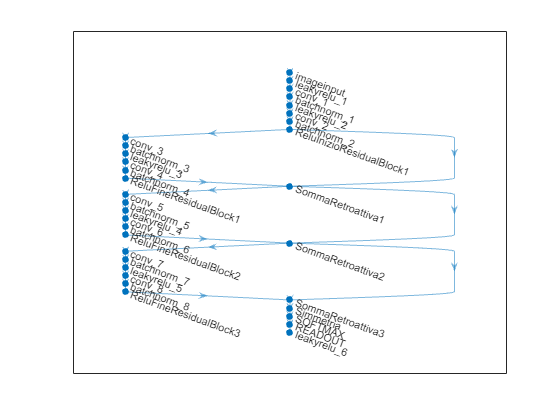

layers = [
    % imageInputLayer - Input layer with 100x100x8 dimensions, no normalization.
    imageInputLayer([100 100 8],'Normalization','none')
    leakyReluLayer
    %convolution2dLayer(1,1,"Bias",zeros(1,1,1),"BiasLearnRateFactor",0,"Name","BatchData")
    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer
    
    %Resi
    leakyReluLayer("Name","ReluInizioResidualBlock1")

    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer

    leakyReluLayer("Name","ReluFineResidualBlock1")

    additionLayer(2,"Name","SommaRetroattiva1")

    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer

    leakyReluLayer("Name","ReluFineResidualBlock2")

    additionLayer(2,"Name","SommaRetroattiva2")

    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(3,32,'Padding',1,"Bias",zeros(1,1,32),"BiasLearnRateFactor",0)
    batchNormalizationLayer

    leakyReluLayer("Name","ReluFineResidualBlock3")

    additionLayer(2,"Name","SommaRetroattiva3")
    
    
    functionLayer(@simmetria,Description="ApplicaSimmetria",Name="Simmetria")
    %sigmoidLayer("Name","SIGMOID")
    softmaxLayer("Name","SOFTMAX")
    convolution2dLayer(1,1,"Bias",zeros(1,1,1),"BiasLearnRateFactor",0,"Name","READOUT")
    leakyReluLayer 
]; 

layers = layerGraph(layers);
layers = connectLayers(layers,'ReluInizioResidualBlock1','SommaRetroattiva1/in2');
layers = connectLayers(layers,'SommaRetroattiva1','SommaRetroattiva2/in2');
layers = connectLayers(layers,'SommaRetroattiva2','SommaRetroattiva3/in2');

figure
plot(layers);

Create a `dlnetwork` object from the layer array.

net = dlnetwork(layers);

## Train Network

Initialize Train variables

numObservations = length(XTrainCSV);
numIterationsPerEpoch = floor(numObservations./TrainSetting.miniBatchSize);
numIterations = TrainSetting.numEpochs * numIterationsPerEpoch; % Total number of iterations for the training progress monitor

iteration = 0;      % iterator for iterations
epoch = 0;          % iterator for epoch

% initialize average Gradient for Adam Optimizer
averageGrad = [];   
averageSqGrad = [];

% initialize average vel for SGD Optimizer
vel = [];

Initialize the `TrainingProgressMonitor` object.

monitor = trainingProgressMonitor(Metrics="Loss",Info=["Epoch","Loss","EpochIteration"],XLabel="Iteration");

Train the model using a custom training loop. 

For each epoch, shuffle (if setted) the data and loop over mini-batches of data. 

Update the network parameters using the `adamupdate` or SGD optimizer. 

At the end of each iteration, display the training progress.

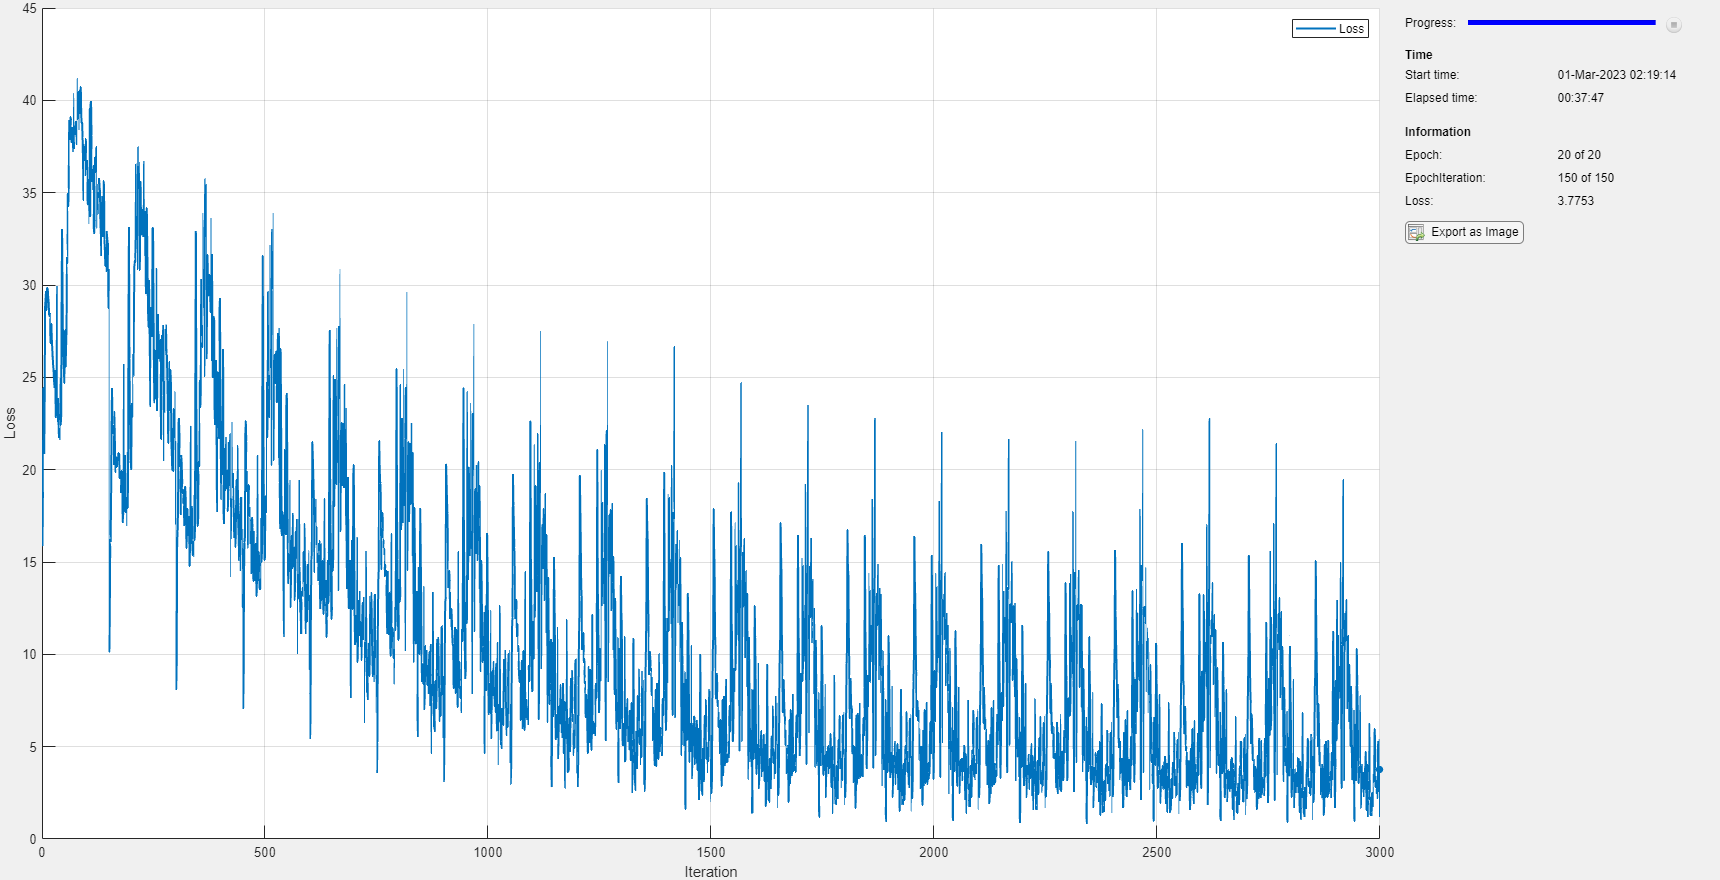

% Keep training until the number of epochs is reached or the monitor signals to stop
while epoch < TrainSetting.numEpochs && ~monitor.Stop
    epoch = epoch + 1;
    
    % If Shuffle is enabled, shuffle the data
    if(TrainSetting.Shuffle)           
        idx = randperm(numObservations);
        XTrainCSV = XTrainCSV(idx);
        TTrainCSV = TTrainCSV(idx);
    end
    
    i = 0;
    while i < numIterationsPerEpoch && ~monitor.Stop
        i = i + 1;
        iteration = iteration + 1;

        % Create a batch of data to use for training
        idx = (i-1)*TrainSetting.miniBatchSize+1:i*TrainSetting.miniBatchSize;
        CellBatch = struct();
        CellBatch.input = XTrainCSV(idx);
        CellBatch.output = TTrainCSV(idx);
        [X,T,dim] = createPaddedBatch(CellBatch);    

        % Convert input and target data to dlarrays
        X = dlarray( single(X), "SSCB" );
        T = dlarray( single(T), "SSBC" );
        
        if canUseGPU % Train on a GPU, if one is available.
            X = gpuArray(X);
        end
        
        % Evaluate the loss and gradients for the current batch
        [loss,gradients] = dlfeval(@modelLoss,net,X,T,dim);
        
        % Update the model weights using the optimizer specified in TrainSetting
        if(TrainSetting.Optimizer)
            [net,averageGrad,averageSqGrad] = adamupdate(net,gradients,averageGrad,averageSqGrad,iteration);
        else            
            [net,vel] = sgdmupdate(net, gradients, vel);
        end 
        
        % Record the loss for the current iteration
        recordMetrics(monitor,iteration,Loss=loss);

        % Update the monitor with information about the current epoch and iteration
        updateInfo(monitor,Epoch=epoch + " of " + TrainSetting.numEpochs,EpochIteration=i + " of " + numIterationsPerEpoch,Loss=loss);
        
        % Update the monitor progress bar
        monitor.Progress = 100 * iteration/numIterations;
    end
end

disp("Net Trained");

Net Trained


fileName = "Nitro_Net_"; 
fileName = fileName + string(datetime("now","Format","yyyy-MM-dd_HH-mm"))+"_"; % Store the time net is created
fileName = fileName + TrainSetting.datasetName + "_";                          % Store the Dataset Used
fileName = fileName + ternOp(TrainSetting.Optimizer,"Adam","SGD") + "_";       % Store the Optimizer Used
fileName = fileName + ternOp(TrainSetting.Shuffle,"Shuffle","Unshuffle");      % Store if dataset was Shuffled or Not
save("./TrainedNetwork/"+fileName+".mat","net","TrainSetting","monitor");
disp("Net Saved");

Net Saved


#### EMPTY THE USELESS VARIABLES

clearvars averageGrad ...
          averageSqGrad ...
          CellBatch ...
          dim ...
          epoch ...
          gradients ...
          i...
          idx ...
          iteration ...
          layers ...
          loss ...
          numIterations ...
          numIterationsPerEpoch ...
          numObservations ...
          T ...
          TTrainCSV...
          vel ...
          XTrainCSV ...
          X ...
          XTrainCSV

# Functions

## Batch Symmetry

Simmetria function takes a 4D input tensor `X` and returns another 4D tensor `out` obtained by averaging `X` with its transpose along the first two dimensions.

Here are the details of what the function does:

- `permute(X,[2 1 3 4])` swaps the first and second dimensions of `X`, effectively transposing it along the first two dimensions.

- `X + permute(X,[2 1 3 4])` adds `X` with its transpose.

- `0.5 * (X + permute(X,[2 1 3 4]))` scales the sum by a factor of 0.5.

- The resulting tensor `out` is returned by the function.

The purpose of this function is to enforce symmetrical weights 

function out = simmetria(X)
    out = 0.5*(X+permute(X,[2 1 3 4]));    
end

## Model Loss Function

This function calculates the loss and gradients of a neural network model given an input batch `X` and corresponding target batch `T`.

Inputs:

- `net`: a neural network model

- `X`: input batch data

- `T`: target batch data

- `dim`: a vector containing the dimension of each input in the batch

Outputs:

- `loss`: the calculated loss of the model on the input batch

- `gradients`: the gradients of the model with respect to its learnable parameters

The function first calls the `forward` function of the neural network model to obtain the predicted output `Y` for the input batch `X`. Then, it calculates the loss for each input in the batch, and appends it to a list `loss`. 

The loss is calculated using mean-squared error between the predicted output and the target output, for each individual input in the batch. 

The loss list `loss` is then averaged to obtain the final loss.

Finally, the gradients of the loss with respect to the learnable parameters of the neural network model are computed using the `dlgradient` function.

function [loss,gradients] = modelLoss(net,X,T,dim)
    Y = forward(net,X);
    batchLength = size(Y,4);    
    loss = [];
    for i = 1:batchLength
        lossPattern = mse(Y(1:dim(i),1:dim(i),1,i),T(1:dim(i),1:dim(i),1,i));
        loss = [loss lossPattern];
    end
    loss = mean(loss);
    gradients = dlgradient(loss,net.Learnables); 
end